MECH532 Exam 2

Jeremy Primus

11/2/2018

Problem 2.

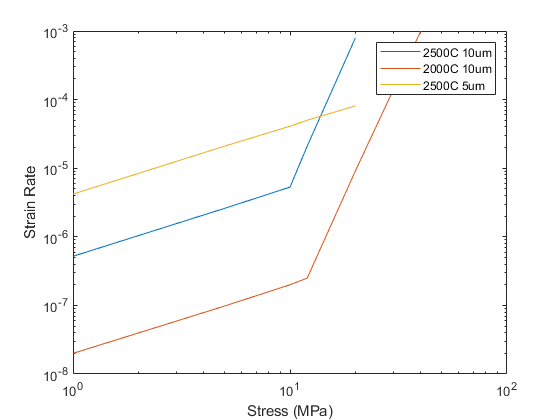

% initialize a data structure 
s.stress = [1 5 10 12 20 40];
s.strain_rate = [5.2e-7 2.6e-6 5.3e-6 2.1e-5 7.9e-4 NaN;
                 2e-8 9.8e-8 2e-7 2.5e-7 9.1e-6 9.9e-4;
                 4.2e-6 2.1e-5 4.1e-5 5e-5 8.1e-5 NaN];
s.temp = [2500; 2000; 2500;]*ones(1,6);
s.grain_size = [10; 10; 5]*ones(1,6);

% plot creep rate vs. stress
figure()
for i = 1:3
    %semilogy(s.stress, s.strain_rate(i,:))
    loglog(s.stress, s.strain_rate(i,:))
    hold on
end
legend('2500C 10um', '2000C 10um', '2500C 5um')
xlabel('Stress (MPa)')
ylabel('Strain Rate')

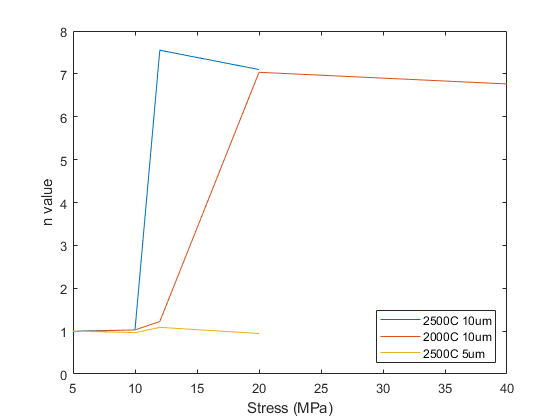

% determine the stress exponent
% approximate the derivative in log-log space
dydx = [diff(log10(s.strain_rate(1,:)))./(diff(log10(s.stress)));
        diff(log10(s.strain_rate(2,:)))./(diff(log10(s.stress)));
        diff(log10(s.strain_rate(3,:)))./(diff(log10(s.stress)))];

% plot the stress exponent to visualize regimes
% plot creep rate vs. stress
figure()    
plot(s.stress(2:5), dydx(1,1:4))
hold on
plot(s.stress(2:6), dydx(2,:))
plot(s.stress(2:5), dydx(3,1:4))

legend({'2500C 10um', '2000C 10um', '2500C 5um'}, 'Location', 'southeast' )
xlabel('Stress (MPa)')
ylabel('n value')

It is apparent when observing both of the above plots, that a change of mechanism occurs for the 10 um grain size materials.  There is a transition from diffusional creep, to power law creep at stresses of 12MPa (@2500C) and 20 MPa (@2000C).

For any creep mechanism, the natural log of the strain rate should scale with 1/kT by scale factor Q.

The distinction between Coble and Nabarro-Herring creep can be made through their temperature dependence, which is an exponential relation encapsulated in the diffusion constant.

By plotting temperature vs strain rate (in logspace) for the two different stress regimes, we can quickly identify whether the temperature dependence is the same between the diffusional creep mechanism and the power law creep (PLC) mechanism.

If the temperature dependance is the same, this indicates that the observed diffusional creep operates through the Nabarro-Herring mechanism, as the PLC equation uses the same Q (energy barrier to disrupt lattice).  Their slope (Q/KT) should then be the same.

If diffusional creep procedes by coble creep, the determined slope should be less for diffusional creep than for PLC.

Activation Energies for creep

k = 1.38e-23;   % boltzmann constant
Qd = (log(s.strain_rate(2,1))-log(s.strain_rate(1,1)))/((1/(k*2500)) - (1/(k*2000)));
Qplc = (log(s.strain_rate(2,5))-log(s.strain_rate(1,5)))/((1/(k*2500)) - (1/(k*2000)));
disp(['Qd = ', num2str(Qd/1.6e-19), ' eV'])

Qd = 2.8101 eV


disp(['Qplc = ', num2str(Qplc/1.6e-19), ' eV'])

Qplc = 3.85 eV


Since Qd, and Qplc differ significantly, it is apparent that coble creep facilitates diffusional creep, as PLC would have the same Q if the diffusional creep were through the lattice.  

It is also apparent by looking at grain size dependence that coble creep facilitates diffusional creep (1/d^3) grain size dependence.

slope = -(log10(s.strain_rate(1,1))-log10(s.strain_rate(3,1)))/(log10(10e-6) - log10(5e-6))

slope = 3.0138

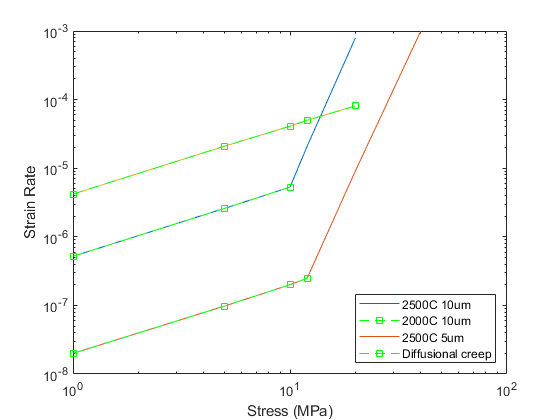

% plot creep rate vs. stress
figure()
for i = 1:3
    loglog(s.stress, s.strain_rate(i,:))
    hold on
    loglog(s.stress([true dydx(i,:) < 1.5]), s.strain_rate(i,[true dydx(i,:) < 1.5]), '--gs')
end
legend({'2500C 10um', '2000C 10um', '2500C 5um','Diffusional creep'}, 'Location','southeast')
xlabel('Stress (MPa)')
ylabel('Strain Rate')

Although the plot legend did not come out correctly, from comparision with the first plot, it is apparent which trace represents which material.  In all cases, the solid line represents the dislocation creep regime, while the dotted line represents the diffusional creep regime.  